## Part 1

### Figure 1

Basic M-K plot

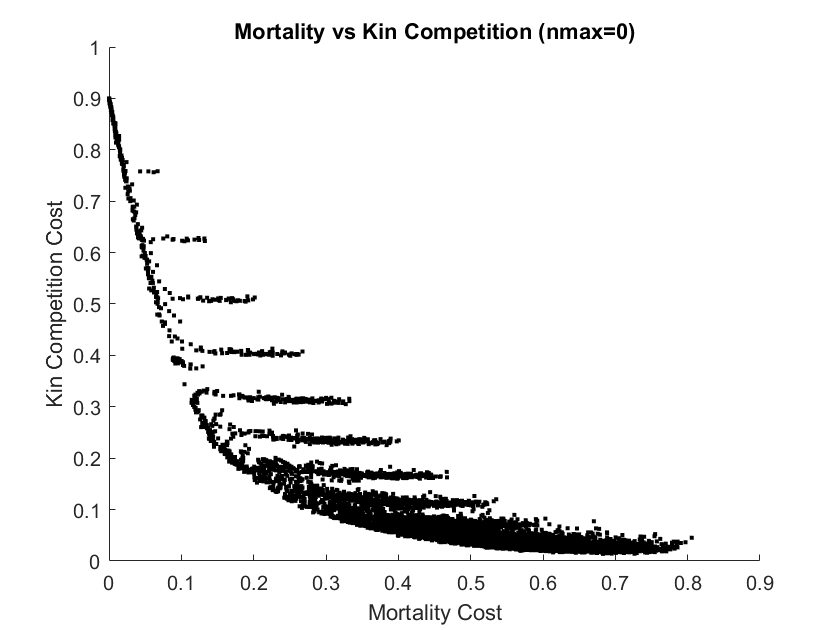

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

figure
hold on
plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')
hold off
%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\1.jpg')

### Figure 2

M-K plot with a couple of points highlighted, and the kernels at those points

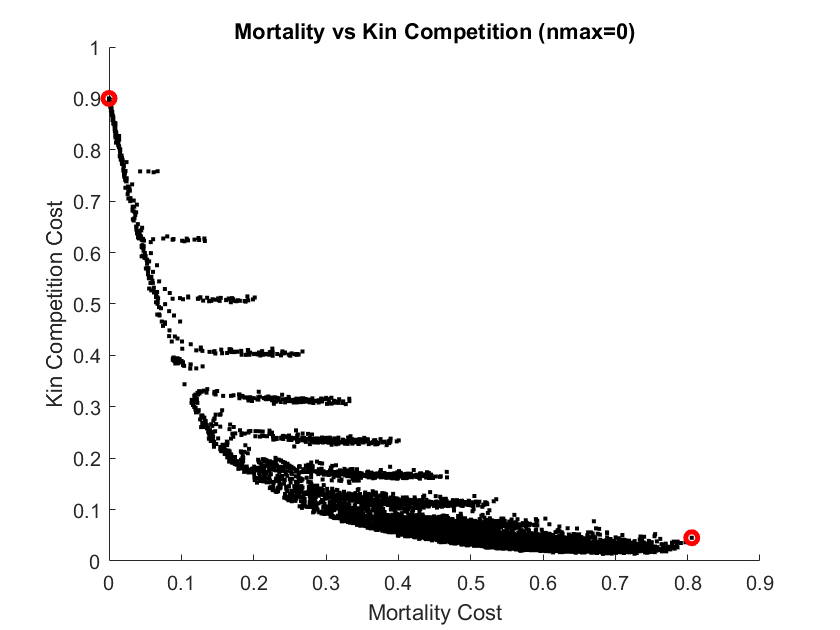

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

pts = [1 6188]; %indices of points to emphasize, and plot kernels for

%2a
figure
hold on
plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')
plot(out_mortcost(pts),out_kincost(pts),'or','LineWidth',2.5)
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=0)')

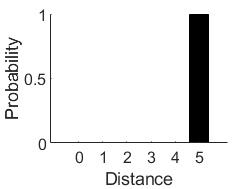

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2a.jpg')

%2b,c
figure
bar(0:5,kernels(pts(1),:),'black')
xlabel('Distance')
ylabel('Probability')
box off
fig_position = get(gcf,'Position');
fig_position(3) = .3*fig_position(3); %width
fig_position(4) = .3*fig_position(4); %height
set(gcf,'Position',fig_position);
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2b.jpg')

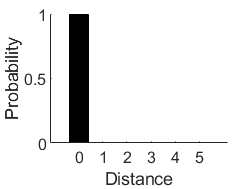


figure
bar(0:5,kernels(pts(2),:),'black')
xlabel('Distance')
ylabel('Probability')
box off
fig_position = get(gcf,'Position');
fig_position(3) = .3*fig_position(3); %width
fig_position(4) = .3*fig_position(4); %height
set(gcf,'Position',fig_position);
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\2c.jpg')

### Figure 3

M-K plot, with fitness colors and boundary line added

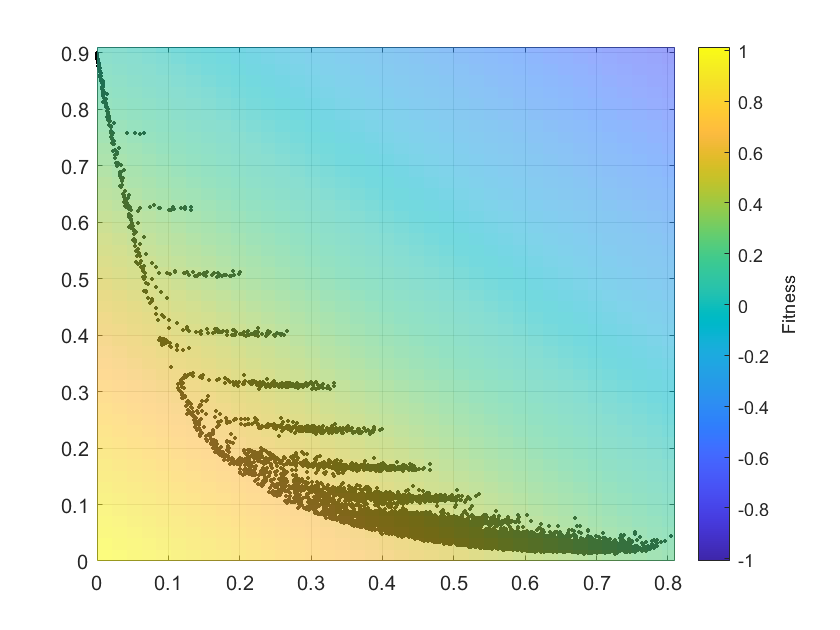

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
xlim([0 0.81])
ylim([0 0.91])
set(fp,'FaceAlpha',0.55)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'k.')
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'k.')

a = colorbar;
a.Label.String = 'Fitness';
%xlabel('Mortality Cost')
%ylabel('Kin Competition Cost')
%title('Mortality vs Kin Competition (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\3.jpg')

### Figure 4

Fitness colors and boundary line only

### Figure 5

Fitness colors, boundary line, and trajectories

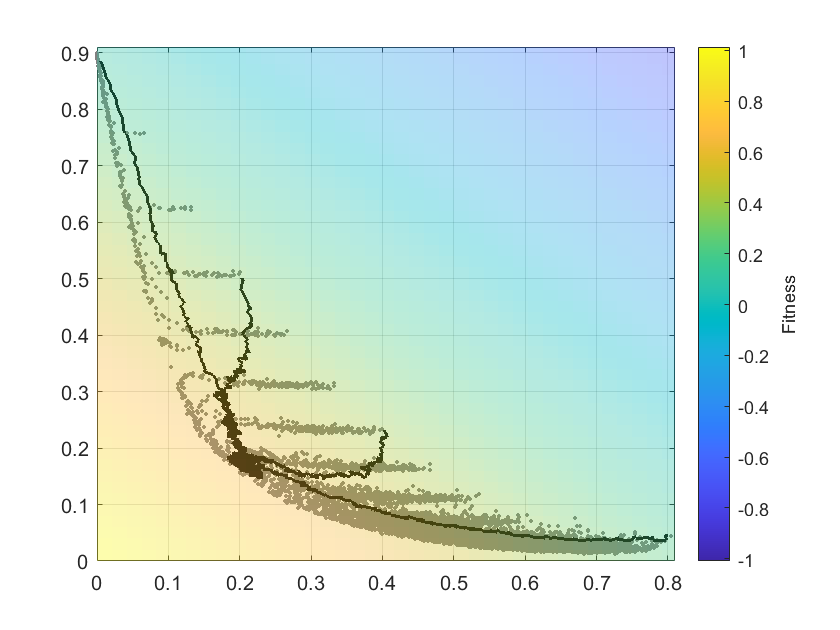

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\weibull_MK.mat')
all_w = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});
clear dist_fitness dist_kincost dist_mortcost kernels out_mortcost out_kincost out_fitness
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_0\fitness_surface.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
xlim([0 0.81])
ylim([0 0.91])
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])
plot(table2array(all_w(:,"Mortality")),table2array(all_w(:,"KinComp")),'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
%xlabel('Mortality Cost')
%ylabel('Kin Competition Cost')
%title('Mortality vs Kin Competition (nmax=0)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\5.jpg')

### Figure 6

Fitness over time (plus kernel over time?)

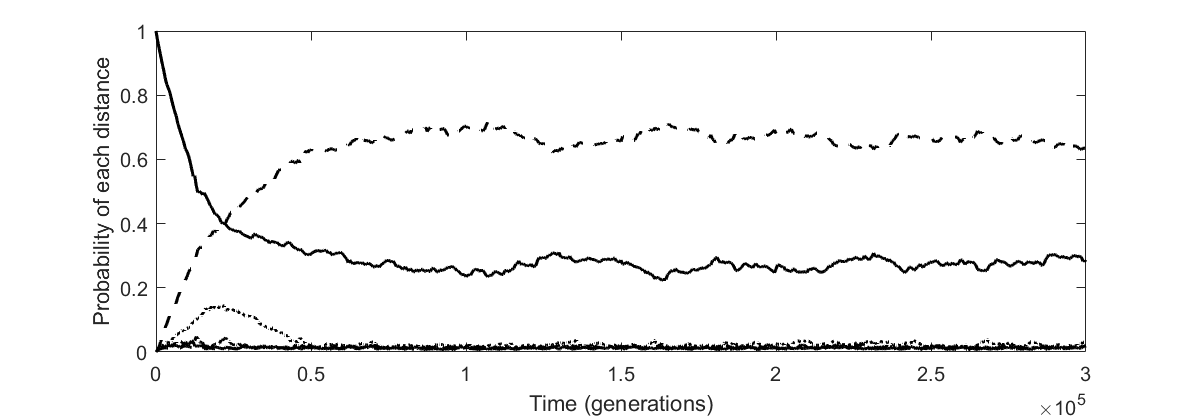

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
fit = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
out_mort = sum(mortality_cost.*dtime_avg,2,'omitnan');
out_kin = sum(kincomp_cost.*dtime_avg,2,'omitnan');

gens_to_plot = [1 500*(1:length(out_kin)/500)];
figure
g = plot(gens_to_plot,dtime_avg(gens_to_plot,:),'LineWidth',1.5,'Color','black');
set(g,{'LineStyle'},{'-';'--';':';'-.';'-';'--'})
ylim([0 1])
xlabel('Time (generations)')
ylabel('Probability of each distance')
fig_position = get(gcf,'Position');
fig_position(3) = 2*fig_position(3); %width
fig_position(4) = .75*fig_position(4); %height
set(gcf,'Position',fig_position);

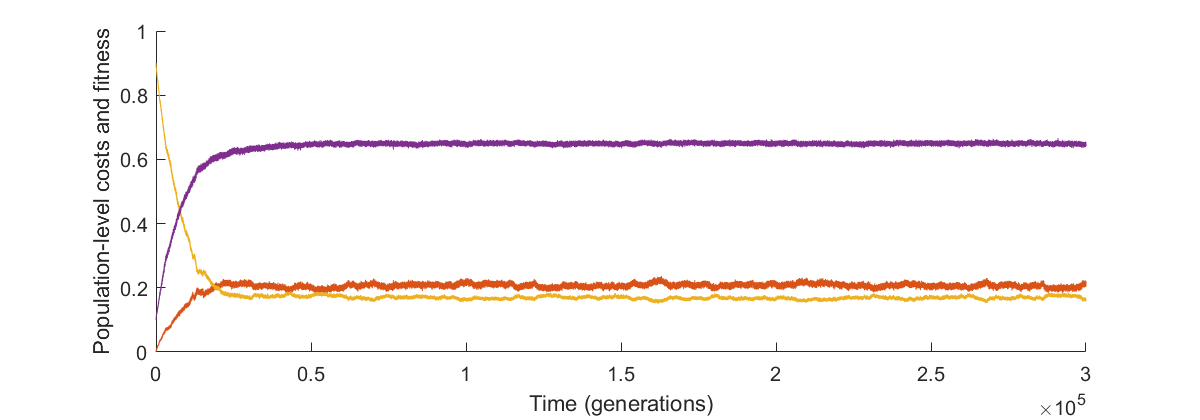

%legend(string(0:5),'Location','eastoutside')
%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6c.jpg')


%% without thinning, just to check that it doesn't change the appearance of the plot in a misleading way
% figure
% g1 = plot(dtime_avg,'LineWidth',1.5);
% set(g1,{'LineStyle'},{'-';'--';':';'-.';'-';'--'})
% ylim([0 1])
% xlabel('Time (generations)')
% ylabel('Probability of each distance')
% fig_position = get(gcf,'Position');
% fig_position(3) = 2*fig_position(3); %width
% fig_position(4) = 1*fig_position(4); %height
% set(gcf,'Position',fig_position);

figure
clf
hold on
plot(out_mort,'-','Color','#D95319')
plot(out_kin,'-','Color','#EDB120')
plot(fit,'-','Color','#7E2F8E')
xlabel('Time (generations)')
ylabel('Population-level costs and fitness')
fig_position = get(gcf,'Position');
fig_position(3) = 2*fig_position(3); %width
fig_position(4) = .75*fig_position(4); %height
set(gcf,'Position',fig_position);
%legend([{'Mortality'} {'Kin Competition'} {'Fitness'}],'Location','eastoutside')
hold off

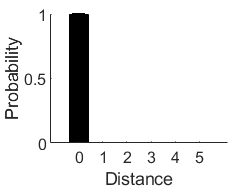

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6d.jpg')

figure
bar(0:5,dtime_avg(1,:),'k')
hold on
er = errorbar(0:5,dtime_avg(1,:),dtime_std(1,:),dtime_std(1,:));
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Probability')
box off
fig_position = get(gcf,'Position');
fig_position(3) = .3*fig_position(3); %width
fig_position(4) = .3*fig_position(4); %height
set(gcf,'Position',fig_position);
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6e.jpg')

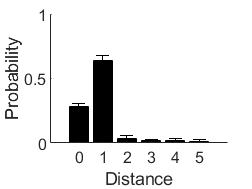


figure
bar(0:5,dtime_avg(300000,:),'k')
hold on
er = errorbar(0:5,dtime_avg(300000,:),dtime_std(300000,:),dtime_std(300000,:));
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Probability')
ylim([0 1])
box off
fig_position = get(gcf,'Position');
fig_position(3) = .3*fig_position(3); %width
fig_position(4) = .3*fig_position(4); %height
set(gcf,'Position',fig_position);
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\6f.jpg')

### Figure 7

ESS kernel (w/variance)

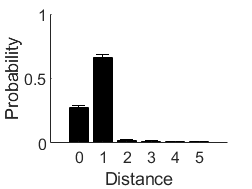

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Probability')
%title('ESS Kernel (nmax=0)')
ylim([0 1])
box off
fig_position = get(gcf,'Position');
fig_position(3) = .3*fig_position(3); %width
fig_position(4) = .3*fig_position(4); %height
set(gcf,'Position',fig_position);
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\7.jpg')



%% they're all the same, so let's just do one
% ESS_mean_br = mean(dtime_br(100000:300000,:));
% ESS_std_br = std(dtime_br(100000:300000,:));
% 
% ESS_mean_ae = mean(dtime_ae(100000:300000,:));
% ESS_std_ae = std(dtime_ae(100000:300000,:));
% 
% ESS_mean_re = mean(dtime_re(100000:300000,:));
% ESS_std_re = std(dtime_re(100000:300000,:));

% tiledlayout(2,2)
% 
% nexttile
% bar(0:5,ESS_mean_tl)
% hold on
% er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_br)
% hold on
% er = errorbar(0:5,ESS_mean_br,ESS_std_br,ESS_std_br);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_ae)
% hold on
% er = errorbar(0:5,ESS_mean_ae,ESS_std_ae,ESS_std_ae);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off
% 
% nexttile
% bar(0:5,ESS_mean_re)
% hold on
% er = errorbar(0:5,ESS_mean_re,ESS_std_re,ESS_std_re);
% er.LineStyle = 'none';
% er.Color = [0 0 0];
% hold off


### Figure 11

Cost-benefit plot by distance for ESS kernel

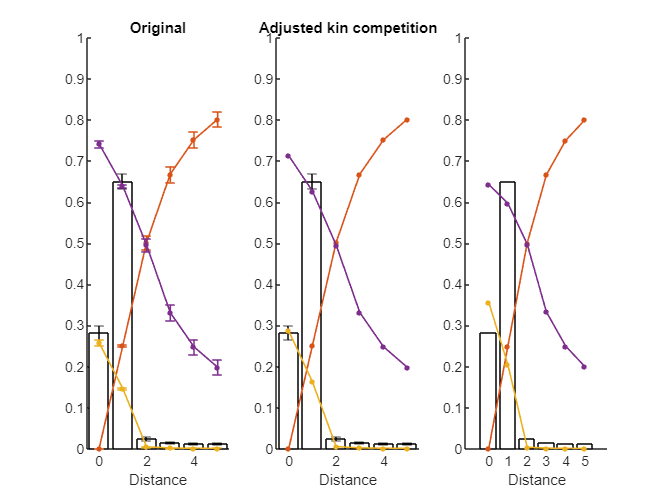

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax0\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=0_del=0.001_b=10_p=1.mat')

kernel_avg = mean(dtime_avg(200000:300000,:),1);
kernel_std = std(dtime_avg(200000:300000,:),1);

fitness = (1-mortality_cost).*(1-kincomp_cost);
fitness_ESS = mean(fitness(200000:300000,:),1);
fitness_STD = std(fitness(200000:300000,:),1);

kincomp_ESS = mean(kincomp_cost(200000:300000,:),1);
kincomp_STD = std(kincomp_cost(200000:300000,:),1);

mortality_ESS = mean(mortality_cost(200000:300000,:),1);
mortality_STD = std(mortality_cost(200000:300000,:),1);


% error bars represent std of each quantity over the last 100000 generations of simulation
figure
tiledlayout(1,3)

nexttile

hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
title('Original')
hold off
%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\11.jpg')

nexttile

kincomp_cost_adj = kincomp_cost.*(10/9);
fitness_adj = (1-mortality_cost).*(1-kincomp_cost_adj);
fitness_ESS_adj = mean(fitness_adj(200000:300000,:),1);
kincomp_ESS_adj = mean(kincomp_cost_adj(200000:300000,:),1);

hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS_adj,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS_adj,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
title('Adjusted kin competition')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off

nexttile
kernelcosts(kernel_avg,0,1);

## Part 2

### Figure 8

Fitness colors, boundary line (or points?), and trajectories for nmax=1,2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_1\fitness_surface_lg.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=1)')
hold off

saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\8a.jpg')

nmax=2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\cost_ben_model\nmax_2\fitness_surface_lg.mat')
all = array2table([kernels out_mortcost out_kincost out_fitness],'VariableNames',{'v0','v1','v2','v3','v4','v5','Mortality','KinComp','Fitness'});

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_tl = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_tl = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_br = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_br = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_ae = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_ae = sum(mortality_cost.*dtime_avg,2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kincosts_re = sum(kincomp_cost.*dtime_avg,2,'omitnan');
mortcosts_re = sum(mortality_cost.*dtime_avg,2,'omitnan');

skip = 100; %increments to skip by
gens_to_use = skip*(1:(g/skip));

f = fit([out_mortcost out_kincost],out_fitness,"poly11");

figure
clf
colormap parula
hold on

fp = plot(f);
view(2)
set(fp,'FaceAlpha',0.35)
set(fp,'EdgeAlpha',0)

plot(out_mortcost,out_kincost,'.','Color',[.5 .5 .5])

plot(mortcosts_tl(gens_to_use,:),kincosts_tl(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_br(gens_to_use,:),kincosts_br(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_ae(gens_to_use,:),kincosts_ae(gens_to_use,:),'k','LineWidth',1.5)
plot(mortcosts_re(gens_to_use,:),kincosts_re(gens_to_use,:),'k','LineWidth',1.5)

a = colorbar;
a.Label.String = 'Fitness';
xlabel('Mortality Cost')
ylabel('Kin Competition Cost')
title('Mortality vs Kin Competition (nmax=2)')
hold off

saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\8b.jpg')

### Figure 9

Fitness over time, nmax=1,2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;
fit_tl = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_br = dtime_avg;
fit_br = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_ae = dtime_avg;
fit_ae = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_re = dtime_avg;
fit_re = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');

figure
clf
hold on
plot(fit_tl)
plot(fit_br)
plot(fit_ae)
plot(fit_re)
xlabel('Time (generations)')
ylabel('Population-level fitness')
title('Fitness over time (nmax=1)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\9a.jpg')

nmax=2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;
fit_tl = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\bottomright\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_br = dtime_avg;
fit_br = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_ae = dtime_avg;
fit_ae = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\rightESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_re = dtime_avg;
fit_re = sum(dtime_avg.*(1 - mortality_cost).*(1 - kincomp_cost),2,'omitnan');

figure
clf
hold on
plot(fit_tl)
plot(fit_br)
plot(fit_ae)
plot(fit_re)
xlabel('Time (generations)')
ylabel('Population-level fitness')
title('Fitness over time (nmax=2)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\9b.jpg')

### Figure 10

ESS kernels (w/variance), nmax=1,2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Population-level probability (mean +/- sd)')
title('ESS Kernel (nmax=1)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\10a.jpg')

nmax=2

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
dtime_tl = dtime_avg;

ESS_mean_tl = mean(dtime_tl(100000:300000,:));
ESS_std_tl = std(dtime_tl(100000:300000,:));

figure
bar(0:5,ESS_mean_tl,'k')
hold on
er = errorbar(0:5,ESS_mean_tl,ESS_std_tl,ESS_std_tl);
er.LineStyle = 'none';
er.Color = [0 0 0];
xlabel('Distance')
ylabel('Population-level probability (mean +/- sd)')
title('ESS Kernel (nmax=2)')
hold off
saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\10b.jpg')


## Figure 12

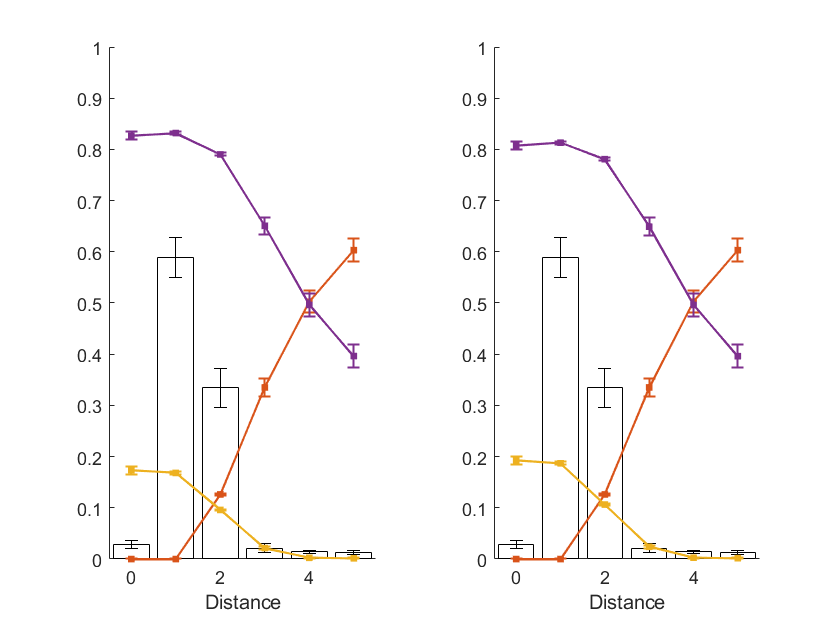

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax1\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=1_del=0.001_b=10_p=1.mat')
kernel_avg = mean(dtime_avg(200000:300000,:),1);
kernel_std = std(dtime_avg(200000:300000,:),1);
fitness = (1-mortality_cost).*(1-kincomp_cost);
fitness_ESS = mean(fitness(200000:300000,:),1);
fitness_STD = std(fitness(200000:300000,:),1);
kincomp_ESS = mean(kincomp_cost(200000:300000,:),1);
kincomp_STD = std(kincomp_cost(200000:300000,:),1);
mortality_ESS = mean(mortality_cost(200000:300000,:),1);
mortality_STD = std(mortality_cost(200000:300000,:),1);

kincomp_cost_adj = kincomp_cost.*(10/9);
fitness_adj = (1-mortality_cost).*(1-kincomp_cost_adj);
fitness_ESS_adj = mean(fitness_adj(200000:300000,:),1);
kincomp_ESS_adj = mean(kincomp_cost_adj(200000:300000,:),1);

tiledlayout(1,2)

nexttile

% error bars represent std of each quantity over the last 100000 generations of simulation
%figure
hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off

nexttile
% error bars represent std of each quantity over the last 100000 generations of simulation
%figure
hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS_adj,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS_adj,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS_adj,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS_adj,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off

%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\12b.jpg')


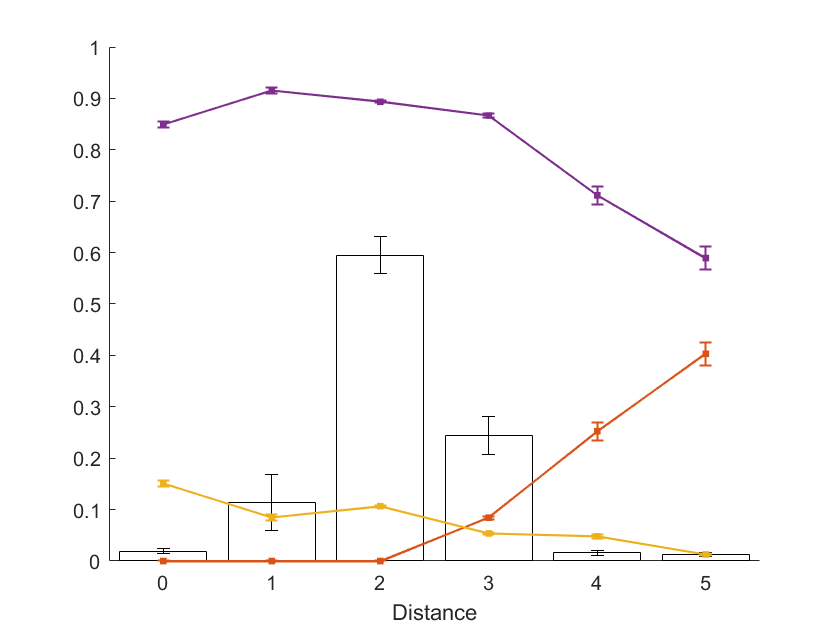

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\topleft\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
kernel_avg = mean(dtime_avg(200000:300000,:),1);
kernel_std = std(dtime_avg(200000:300000,:),1);
fitness = (1-mortality_cost).*(1-kincomp_cost);
fitness_ESS = mean(fitness(200000:300000,:),1);
fitness_STD = std(fitness(200000:300000,:),1);
kincomp_ESS = mean(kincomp_cost(200000:300000,:),1);
kincomp_STD = std(kincomp_cost(200000:300000,:),1);
mortality_ESS = mean(mortality_cost(200000:300000,:),1);
mortality_STD = std(mortality_cost(200000:300000,:),1);



% error bars represent std of each quantity over the last 100000 generations of simulation
figure
hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off
%saveas(gcf, 'C:\Users\eschlatter\Dropbox\DispersalEvolution\figures\12c.jpg')

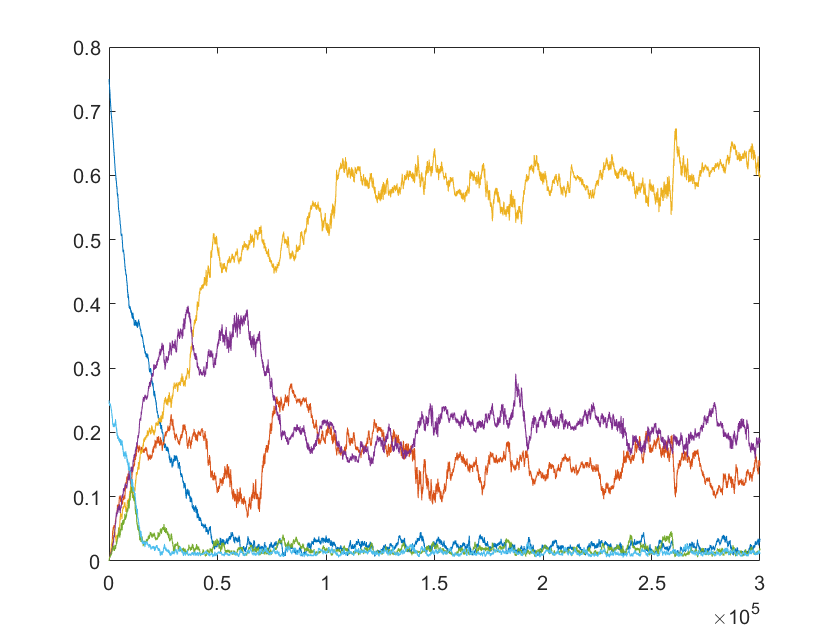

clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20230525\nmax2\aboveESS\IBM_bounded_sx=2_sy=512_nbins=6_nmax=2_del=0.001_b=10_p=1.mat')
figure
clf
plot(dtime_avg)

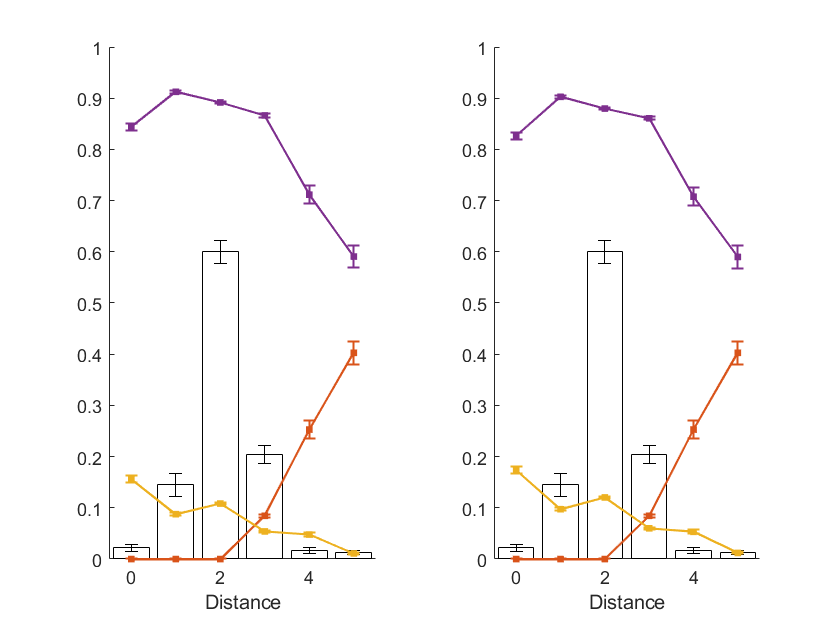


kernel_avg = mean(dtime_avg(200000:300000,:),1);
kernel_std = std(dtime_avg(200000:300000,:),1);
fitness = (1-mortality_cost).*(1-kincomp_cost);
fitness_ESS = mean(fitness(200000:300000,:),1);
fitness_STD = std(fitness(200000:300000,:),1);
kincomp_ESS = mean(kincomp_cost(200000:300000,:),1);
kincomp_STD = std(kincomp_cost(200000:300000,:),1);
mortality_ESS = mean(mortality_cost(200000:300000,:),1);
mortality_STD = std(mortality_cost(200000:300000,:),1);

kincomp_cost_adj = kincomp_cost.*(10/9);
fitness_adj = (1-mortality_cost).*(1-kincomp_cost_adj);
fitness_ESS_adj = mean(fitness_adj(200000:300000,:),1);
kincomp_ESS_adj = mean(kincomp_cost_adj(200000:300000,:),1);

figure
tiledlayout(1,2)

nexttile

% error bars represent std of each quantity over the last 100000 generations of simulation
%figure
hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off

nexttile
% error bars represent std of each quantity over the last 100000 generations of simulation
%figure
hold on
bar(0:5,kernel_avg,'w')
er = errorbar(0:5,kernel_avg,kernel_std,kernel_std);
er.LineStyle = 'none';
er.Color = [0 0 0];

plot(0:5,mortality_ESS,'.-','Color','#D95319','LineWidth',1,'MarkerSize',10)
errorbar(0:5,mortality_ESS,mortality_STD/2,'Color','#D95319','LineWidth',1,'MarkerSize',10)

plot(0:5,kincomp_ESS_adj,'.-','Color','#EDB120','LineWidth',1,'MarkerSize',10)
errorbar(0:5,kincomp_ESS_adj,kincomp_STD/2,'Color','#EDB120','LineWidth',1,'MarkerSize',10)

plot(0:5,fitness_ESS_adj,'.-','Color','#7E2F8E','LineWidth',1,'MarkerSize',10)
errorbar(0:5,fitness_ESS_adj,fitness_STD/2,'Color','#7E2F8E','LineWidth',1,'MarkerSize',10)

legend('kernel','mortality','kin competition','fitness')
xlabel('Distance')
ylim([0 1])
xlim([-0.5 5.5])
legend('off')
hold off